clearvars

## Config

mapData.scale = 50;
mapData.maxViewDist = 6;
mapData.x = round(26.5*mapData.scale);
mapData.y = round(13.5*mapData.scale);
mapData.placingResolution = round(mapData.x/10);


## Map Parse with Laser

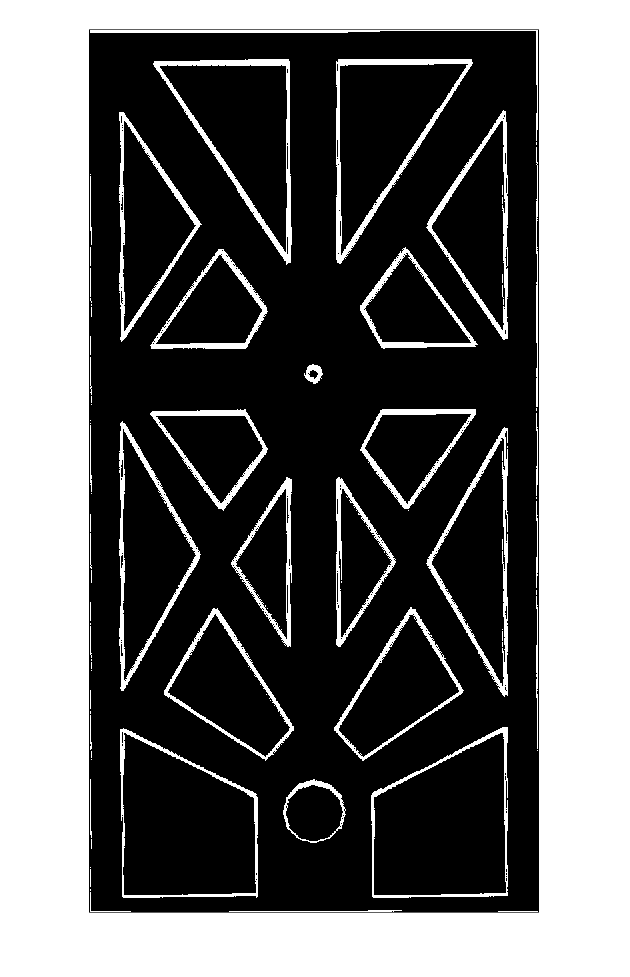

BW = zeros(mapData.x,mapData.y);
robotName = 'Marvin';
laserName = 'LMS100';

for x = 1:mapData.x
    for y = 1:mapData.y
        if 0 == mod(x,mapData.placingResolution) || x == round(0.5*mapData.scale) 
            % Front
            theta = 0;
            apoloPlaceMRobot(robotName, [x/mapData.scale,y/mapData.scale,0], theta);
            ld = apoloGetLaserData(laserName);
            apoloUpdate();
            BW = mapFromLaser(ld,mapData,BW,[x,y,theta]);
            pause(0.001)
            
            % Back
            theta = pi;
            apoloPlaceMRobot(robotName, [x/mapData.scale,y/mapData.scale,0], theta);
            ld = apoloGetLaserData(laserName);
            apoloUpdate();
            BW = mapFromLaser(ld,mapData,BW,[x,y,theta]);
            pause(0.001)
        end
    end
end

imshow(BW)

mapRaw = BW;
% save('jardinBinMapParsed.mat',"BW");

## Processing

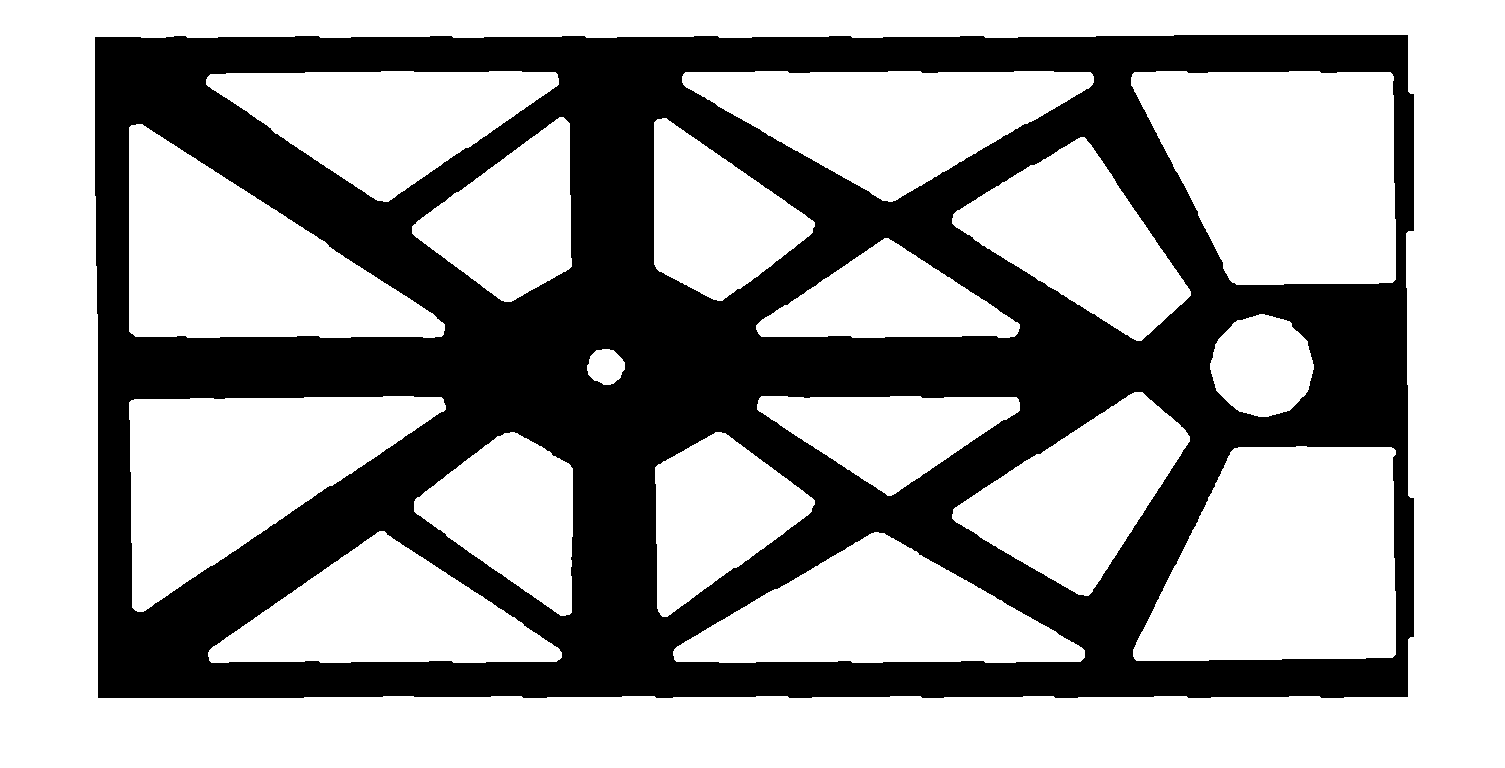

se = offsetstrel('ball',4,4);
BW = imdilate(mapRaw,se);
BW = imfill(BW,'holes');
BW = imerode(BW,se);
BW = imrotate(BW,90);
BW = imbinarize(BW);
mapProcessed = BW;

imshow(BW)

% save('jardinBinMapCorrectAndDilated.mat',"BW");

## Add Fountain

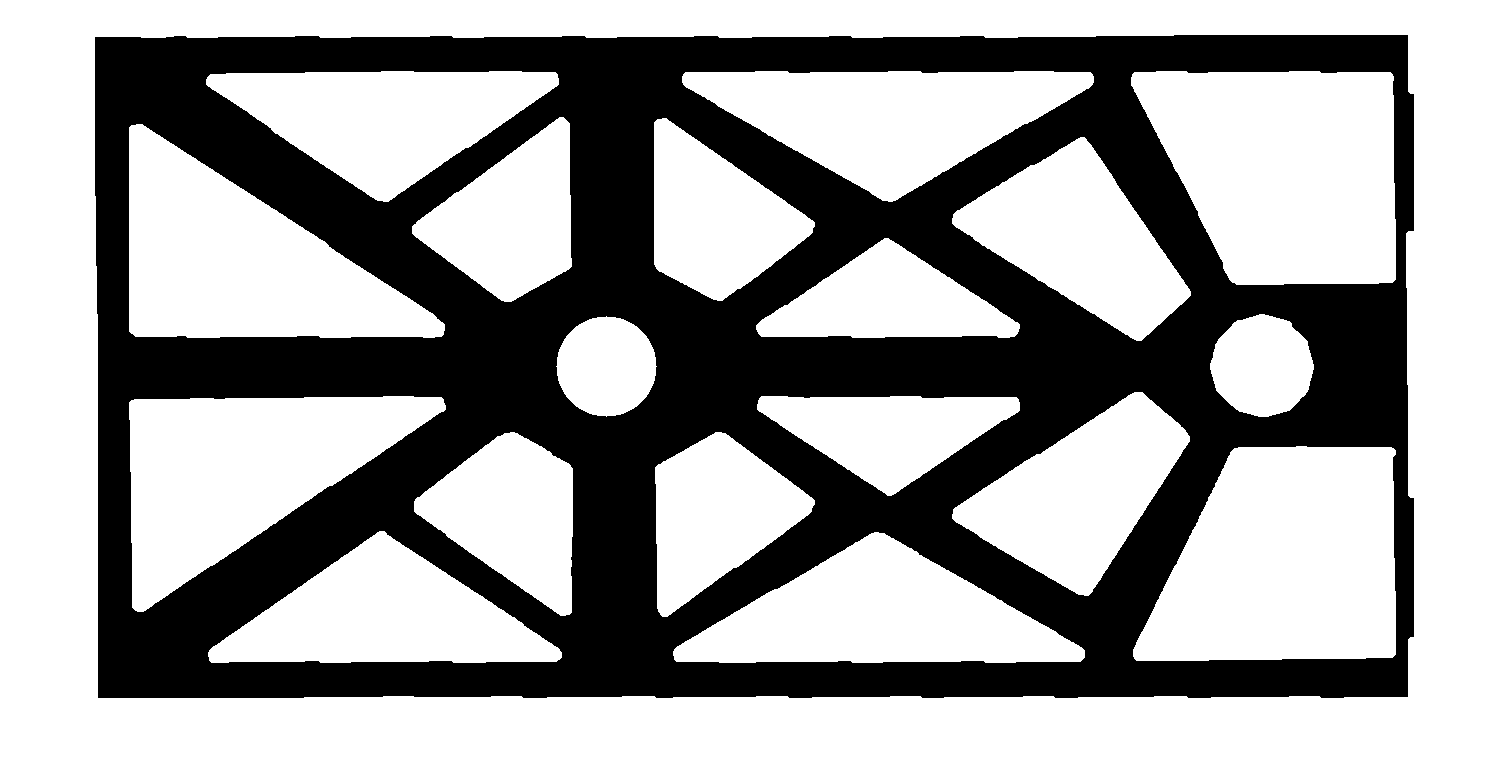

fountain.center = [ round(10.35 * mapData.scale),...
                    round(6.75  * mapData.scale)        ];
fountain.radius = round(1.0 * mapData.scale);

% Create the image.
[columnsInImage, rowsInImage] = meshgrid(1:mapData.x, 1:mapData.y);
% Create the circle in the image.
circlePixels = (rowsInImage - fountain.center(2)).^2 ...
    + (columnsInImage - fountain.center(1)).^2 <= fountain.radius.^2;

BW = BW | circlePixels;
imshow(BW)

mapFountain = BW;
% save('jardinBinMapCorrectAndDilated.mat',"BW");

## Save

BW = mapRaw;
save('jardinBinMapParsed.mat',"BW");
BW = mapProcessed;
save('jardinBinMapCorrectAndDilated.mat',"BW");
BW = mapFountain;
save('jardinBinMapWithFountain.mat',"BW");

function [BW] = mapFromLaser(...
    ld,...          % Laser data
    mapData,...     % Data from the map
    BW,...          % Map in where to add obstacles
    X)              % Coordinates of the robot

for i = 1:length(ld)
    angl = (i/length(ld))*3*pi/2 - 3*pi/4 + X(3);
    dist = ld(i);
    if dist < mapData.maxViewDist
        % Rellenamos un pixel encontrado
        indx = min([mapData.x-1,max([2,     round(X(1)+cos(angl)*dist*mapData.scale)])]);
        indy = min([mapData.y-1,max([2,     round(X(2)+sin(angl)*dist*mapData.scale)])]);
        BW(indx,indy) = 255;
    end
end
end
